# Offset-free State Space MPC using Innovation Bias Approach 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction

   Vanilla MPC formulations we developed in Module 5 used internal model as an open loop without any output feedback. As a consequence, the resulting formulation can be used only for open loop stable systems. This limitation can be overcome if we use a state estimator for implementing an MPC scheme. In this chapter we initially extend the vanilla MPC formulation developed in Module 5 by including a state estimator with output feedback as the internal model for MPC. Subsequently, we propose an alternate output tracking formulation, which is similar to the initial versions of MPC formulations used in the industrial practice. 

**Learning Objectives**

- To understand MPC formulation using a closed loop observer

- To understand role of disturbance filter in reducing fluctuations in manipulated inputs 

## Output Tracking MPC with State Estimator 

   Let us assume that the system/plant may evolve as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d \;d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\;+v\left(k\right)
\end{array}$  ------(1) 

where $\left\lbrace d\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown/unmeasured disturbance input influencing the system dynamics and $\left\lbrace v\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown disturbance in the measured output. Now we relax the assumption that systems state are perfectly measured and assume that only the output signal, i.e. $y\left(k\right)$, is measured. The state feedback formulation of MPC, however,  requires an estimate of the current state for initializing the model predictions. The MPC controller can use an observer to estimate the states as follows 

$\hat{x\;} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)+Le\left(k\right)$---------(2)

$y\left(k\right)=C\hat{x\;} \left(k\right)+e\left(k\right)$--------(3)

and use $\hat{x} \left(k\right)$ estimated as 

$\begin{array}{l}
\hat{x\;} \left(k\right)=\Phi \widehat{x} \left(k-1\right)+\Gamma u\left(k-1\right)+L\;e\left(k-1\right)\\
\;\;\;\;\;\;\;\;\;\;e\left(k-1\right)=y\left(k-1\right)-C\hat{x\;} \left(k-1\right)
\end{array}$  ------(4)

for initializing the model predictions instead of the true state,$x\left(k\right)$. The innovation signal, $e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$, computed using (3) contains the information about the unmeasured disturbances and model plant mismatch (MPM).  Now, given a guess of future manipulated inputs 

${\mathrm{U}}_p \left(k\right)=\left\lbrace u\left(k|k\right),u\left(k+1|k\right),\ldotp \ldotp \ldotp ,u\left(k+p-1|k\right)\right\rbrace$ -----(5)

 the internal model (2) and (3) can be used recursively over the prediction horizon 

  $\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+\textrm{Le}\left(k+j\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(6)


$$\hat{y} \left(k+j\right)=\textrm{Cz}\left(k+j\right)+e\left(k+j\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$$


Since the future measurements are not available, we need to introduce a simplifying assumption regarding the future innovations, $e\left(k+j\right)$,  while carrying out predictions. It is assumed that the future innovations remain constant at the current values $e\left(k\right)$, i.e. 

$e\left(k+j+1\right)=e\left(k+j\right)\;\;$  ------(7)

Under this assumption, the prediction model reduces to 

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+L\;e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(8)


$$\hat{y} \left(k+j\right)=\textrm{Cz}\left(k+j\right)+e\left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$$


As observed from the simulation exercise at the end of the last lesson, the high frequency component in $e\left(k\right)$ can lead to undue oscillations in the input moves. When $d\left(k\right)$ and $v\left(k\right)$ are zero mean white noise signals and there is no drifting unmeasured disturbance or MPM, it can be shown that the innovation sequence is also a zero signal. However, the innovation signal becomes biased (non-zero mean) when the drifting unmeasured disturbance affect the system dynamics or MPM introduced due to process nonlinearity and approximation errors. The simulation exercise at the end of the previous lesson demonstrated that the filtered innovation captures the drifting mean of the innovations, which needs to be dealt with for achieving offset fee control. The low frequency drifting mean of $\left\lbrace e\left(k\right)\right\rbrace$can be estimated using a ***robustness filter ***of the form

$\begin{array}{l}
e_f \left(k\right)=\Phi_e e_f \left(k-1\right)+\left(I-\Phi_e \right)e\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\alpha_1  & \alpha_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \alpha_1 
\end{array}\right\rbrack 
\end{array}$  ------(9)

 where  $0\le \alpha_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters. Using this filtered signal, the assumption about the future innovations is changed as follows  

$e\left(k+j\right)=e_f \left(k\right)\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p$  ------(10)

and $e_f \left(k\right)$ is used in prediction of $z\left(k+1\right)$, i.e. 

$z\left(k+1\right)=\Phi \;\hat{x} \left(k\right)+\Gamma u\left(k|k\right)+Le_f \left(k\right)$ -----(11)

Thus, the prediction model can be changed to

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+L\;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(12)

$y\left(k+j\right)=\textrm{Cz}\left(k+j\right)+e_f \left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$  ------(13)

In addition, the output setpoint changes can be introduced by filtering through low pass unity gain filter to avoid sudden changes in the manipulated inputs.

 $\begin{array}{l}
r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\beta_1  & \beta_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \beta_r 
\end{array}\right\rbrack 
\end{array}$  ------(14)

where  $0\le \beta_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameter. Now, to be consistent with the prediction model, the target state and input calculations need to be modified as follows : when $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $\begin{array}{l}
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u}_s \left(k\right)={\left(G\right)}^{-1} \;\left(r_f \left(k\right)-G_e \;e_f \left(k\right)\right)\\
\textrm{where}\;G=\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)\;\;\;\;\textrm{and}\;\;\;G_e =\left(I+C{\left(I-\Phi \right)}^{-1} L\right)
\end{array}$   ------(15)

When $u_s \left(k\right)$ computed using (15) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(16)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e_f \left(k\right)$ ------(17) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (18)

After solving the optimization problem, $x_s \left(k\right)$ can be found using 

$x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s \left(k\right)+L{\mathrm{e}}_f \left(k\right)\right)$ ------(19)

Now, using the prediction model, we present two MPC formulations: (a) State Space MPC and (b) Output Tracking MPC. These are two distinct forms and cannot be converted from one to another by simple variable transformations. 

###  State Space MPC

This is modification of the vanilla MPC formulations introduced in Module 3 and 5.  


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$ -----(20)

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+L\;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(21)

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(22) 

To keep the treatment simple, we have only retained input bound constraints. However, other constraints such as, input rate constraints or output bounds can be introduced in the formulation. Further, the cost function can be modified by including input rate penalty terms. Note that the state weighting matrix is chosen as$W_x =C^T W_y C$  where $W_y$ is +ve definite output tracking error weighting matrix. 

### Output Tracking MPC 

This is closer to similar to the initial versions of MPC formulations used in the industrial practice. 


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r_f \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_f \left(k\right)\right\|}^2 }_{W_y } +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} } \right\rbrace$  ------(23)


$$\begin{array}{l}
\Delta u\left(k+j|k\right)=u\left(k+j|k\right)-\Delta u\left(k+j-1|k\right)\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k|k\right)=\Delta u\left(k|k\right)-u\left(k-1\right)
\end{array}$$


Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+L\;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(24)


$$\hat{y} \left(k+j\right)=\textrm{Cz}\left(k+j\right)+e_f \left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$$


     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(25) 

Again, to keep the treatment simple, we have only retained input bound constraints. However, other constraints such as, output bounds or those arising from use of control horizon smaller than the prediction horizon, can be introduced in this formulation. Further, the cost function can be modified by including input target penalty terms. The matrix $W_{y,\infty }$ appearing on the R.H.S. of the above equation can be found by solving discrete Lyapunov equation when $\rho \left(\Phi \right)<1$

${\Phi^T W_{y,\infty } \Phi -W}_{y,\infty } ={-C}^T W_y C$ ------(26)

Note that this variant of MPC also allows a time varying setpoint trajectory $\left\lbrace r\left(k+j\right):j=0,1,\ldotp \ldotp \ldotp ,p\right\rbrace \;$over the future horizon, i.e. the loss function can be of the form 

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r\left(k+p\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r\left(k+j\right)\right\|}^2 }_{W_y } +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} } \right\rbrace$  ------(27)

Such loss functions are relevant in applications such as robotics, batch process control and control of drones.  

### **Innovation Bias Approach: Algorithm Summary**

   Since innovation sequence, $\left\lbrace e\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ is used for offset removal, we call this approach as the **Innovation Bias formulation** of MPC. The innovation bias MPC formulation is schematically depicted in **Figure 1.**

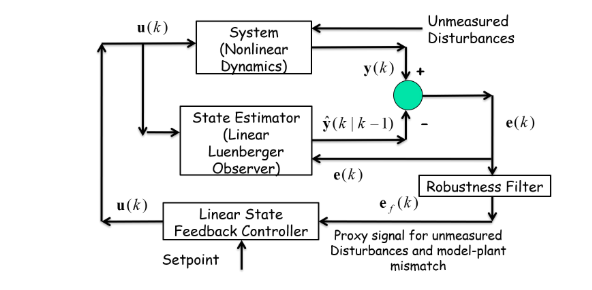

**Figure 1: MPC implementation using Innovation Bias Approach**

 The steps involved in the modified MPC formulations at a $k^{\textrm{th}}$ sampling instant 

- Step 1: Acquire measurement $y\left(k\right)$ from the plant and find the mismatch signal, $\hat{e} \left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$

- Step 2: Compute filtered model plant mismatch signal, ${\hat{e} }_f \left(k\right)$, using equation (9)

- Step 3: Compute filtered setpoint $r_f \left(k\right)$ using equation (14) 

- Step 4: Compute target states and inputs ($\left.x_s \left(k\right),u_s \left(k\right)\right)$ 

- Step 5: Solve the constrained optimization problem (State Space or Output tracking MPC formulation) 

- Step 6: Set $u\left(k\right)=u^* \left(k|k\right)$ and update the internal model states using state estimator

- Step 7: Communicate $u\left(k\right)$ to the plant 

Note that, when $\rho \left(\Phi \right)<1$, choosing the $L$ to be a null matrix, i.e.  $L=\left\lbrack 0\right\rbrack$, reduces the controller vanilla MPC formulation that uses the internal model as an ***open loop observer*** (without output feedback) as discussed in Lessons 2 and 4 of Module 5. Figure 2 shows the block diagram for special case of innovation approach, which uses open loop observer. In this case, the observer gain matrix  $L=\left\lbrack 0\right\rbrack$. 

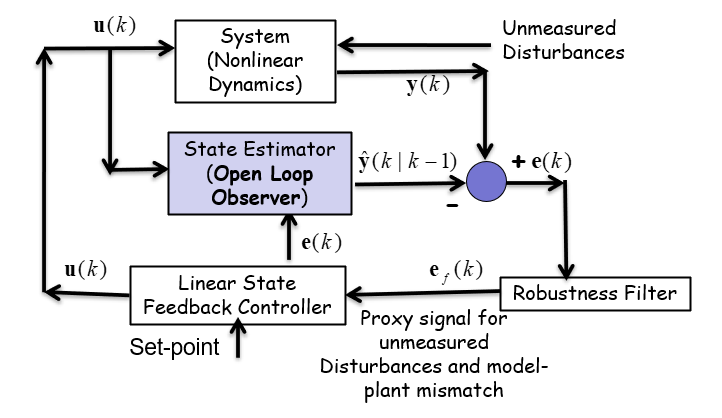

**Figure 2:Innovation Bias Approach:Special case with open loop observer**

## Transformation of State Space MPC to QP Problem 

Using the prediction model (11) repeatedly over the prediction horizon, we can write 

$\begin{array}{l}
z\left(k+j\right)=\Phi^j \hat{x} \left(k\right)+\Phi^{j-1} \Gamma u\left(k|k\right)+\Phi^{j-2} \Gamma u\left(k+1|k\right)+\ldotp \ldotp \ldotp \ldotp \ldotp +\Gamma u\left(k+j-1|k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(\Phi^{j-1} +\Phi^{j-2} +\ldotp \ldotp \ldotp \ldotp \ldotp +I\right)\;L\;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;
\end{array}$   -----(28)

Defining the future input vector, $U_f \left(k\right)$, and predicted output vector, $Z_p \left(k\right)$, over the future horizon as

$U_f \left(k\right)={\left\lbrack {u\left(k|k\right)}^T \;{u\left(k+1|k\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {u\left(k+p-1|k\right)}^T \right\rbrack }^T$   ------(29)

$Z_p \left(k\right)={\left\lbrack {z\left(k+1\right)}^T \;{z\left(k+2\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {z\left(k+p\right)}^T \right\rbrack }^T$-------------------(30)

the prediction model over the entire prediction horizon given by equation (8) can be expressed as a single matrix expression 

$Z_p \left(k\right)=S_x \hat{x} \left(k\right)+S_u U_f \left(k\right)+S_e \;e_f \left(k\right)$  -----(31) 

where

  
$$S_x =\left\lbrack \begin{array}{c}
\Phi \\
\Phi ²\\
\cdots \\
\Phi^p 
\end{array}\right\rbrack \;\;\;;\;\;\;S_u =\left\lbrack \begin{array}{cccc}
\Gamma  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \ldotp  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\Phi \Gamma  & \Gamma  &  & \\
\ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp \\
\Phi^{p-1} \Gamma  & \Phi^{p-2} \Gamma  & \ldotp \ldotp \ldotp \ldotp  & \Gamma 
\end{array}\right\rbrack \;\;\textrm{and}\;\;\;\;S_e =\left\lbrack \begin{array}{c}
L\\
\left(\Phi +I\right)\;L\\
\ldotp \ldotp \ldotp \ldotp \\
\left(\Phi^{p-1} +\Phi^{p-2} +\ldotp \ldotp \ldotp +I\right)\;L
\end{array}\right\rbrack$$


Note that matrices $S_x$ and $S_u$ are identical to the matrices defined by [*equation (19) in Lesson 6 of Module 3 *](matlab:open('../3. Linearized Models for MPC Formulation/L06_MPCReformulationusingLinearPerturbationModel.mlx')) and the only new matrix is $S_e$.  

$Z_p \left(k\right)=S_x \hat{x} \left(k\right)+S_u U_f \left(k\right)+S_e \;e_f \left(k\right)$  -----(32) 

Let us introduce a vector to represent the free response of the system as 

$Z_f \left(k\right)=S_x \hat{x} \left(k\right)+S_e \;e_f \left(k\right)$  ------(33)

and rewrite $Z_p \left(k\right)$ as follows 

$Z_p \left(k\right)=Z_f \left(k\right)+S_u U_f \left(k\right)$  -----(34)

Defining stacked target vectors 

$U_s \left(k\right)=\left\lbrack \begin{array}{c}
u_s \left(k\right)\\
\ldotp \ldotp \ldotp \ldotp \\
u_s \left(k\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
I_{m\times m} \\
\ldotp \ldotp \ldotp \ldotp \\
I_{m\times m} 
\end{array}\right\rbrack u_s \left(k\right)={\mathbf{I}}_U u_s \left(k\right)\;\;\;\;\textrm{and}\;\;X_s \left(k\right)=\left\lbrack \begin{array}{c}
x_s \left(k\right)\\
\ldotp \ldotp \ldotp \ldotp \\
x_s \left(k\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
I_{n\times n} \\
\ldotp \ldotp \ldotp \ldotp \\
I_{n\times n} 
\end{array}\right\rbrack ={\mathbf{I}}_X x_s \left(k\right)\;\;\;$ ----------(35)

the cost function in equation (23) can be expressed as 

$J={\left(Z_p \left(k\right)-X_s \left(k\right)\right)}^T {\mathbf{W}}_X \left(Z_p \left(k\right)-X_s \left(k\right)\right)+{\left(U_f \left(k\right)-U_s \left(k\right)\right)}^T {\mathbf{W}}_U \left(U_f \left(k\right)-U_s \left(k\right)\right)$ -----(36)

where ${\mathbf{W}}_X$ and ${\mathbf{W}}_U$ are block diagonal weighting matrices as defined in Lesson 2 of Module 5. Now consider expansion of the first term in the R.H.S. of (34), i.e. 

${\left(Z_p \left(k\right)-X_s \left(k\right)\right)}^T {\mathbf{W}}_X \left(Z_p \left(k\right)-X_s \left(k\right)\right)={\left(S_u U_f \left(k\right)+\left(Z_f \left(k\right)-X_s \left(k\right)\right)\right)}^T {\mathbf{W}}_X \left(S_u U_f \left(k\right)+\left(Z_f \left(k\right)-X_s \left(k\right)\right)\right)$  ------(37)

From the viewpoint of optimization terms ${\left(Z_f \left(k\right)-X_s \left(k\right)\right)}^T {\mathbf{W}}_X \left(Z_f \left(k\right)-X_s \left(k\right)\right)$ can be ignored and only quadratic and linear terms in $U_f \left(k\right)$ need to be retained. Similarly, from the second term in J, ${\left(U_s \right)}^T {\mathbf{W}}_X \left(U_s \right)$ can be ignored. Thus, with some algebraic manipulations, the QP cost function can be reduced to  

$J\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(38a) 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)\;\\
\textrm{and}\;\;F\left(k\right)=2\left({\left(S_u \right)}^T {\mathbf{W}}_X \right)\;\left(Z_f \left(k\right)-{\mathbf{I}}_X x_s \left(k\right)\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s \left(k\right)
\end{array}$ ------(38b)

The problem of finding target state and target inputs can also be reduced to a QP problem as follows:  

$\frac{1}{2}\;{\left({\;u}_s \left(k\right)\right)}^T \;H_s \;{\;u}_s \left(k\right)+F_s^T {\;u}_s \left(k\right)$ ------(39)


$$H_s ={2G}^T W_{\textrm{ys}} G\;\;\;\textrm{and}\;\;\;F_s \left(k\right)=-2\;G^T W_{\textrm{ys}} \left(r_f \left(k\right)-{G_e \hat{e} }_f \left(k\right)\right)\;$$


and the constrained optimization problem in equations (16) - (18) reduces to the following QP problem: 


$$\min_{u_s \left(k\right)} \;\;\;\frac{1}{2}\;{\left({\;u}_s \left(k\right)\right)}^T \;H_s \;{\;u}_s \left(k\right)+{\left(F_s \left(k\right)\right)}^T {\;u}_s \left(k\right)$$


subject to 


$$\left\lbrack \begin{array}{c}
I_m \\
{-I}_m 
\end{array}\right\rbrack {\;u}_s \left(k\right)\le \left\lbrack \begin{array}{c}
u_H \\
u_L 
\end{array}\right\rbrack$$


## Q Tank Process Simulation: Disturbance and MPM Rejection

 
clear all 
close all

global QTank U_k D_k

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1**: Select the operating point for Q Tank process.  

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end


**Task 2**: Set the simulation run time N = 500 to study only the disturbance rejection and N = 800 to additionally see servo response. 

N = 500 ;      % Simulation run time


**Initialize linear model for plant simulation **


phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;


**Initialize internal model for MPC **

mpc.phy= phy ;  
mpc.gam = gam ;
mpc.gam_d = gam_d ; 
mpc.C_mat = C_mat ;
mpc.n_st = n_st ; mpc.n_op = n_op ;  mpc.n_ip = n_ip ; 

QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;
Q_mat = 0.0025 ;
R_mat = QTank.R_mat ;

**MPC Tuning Parameters**

**Task 3: **Set the prediction horizon n_pred to interval >= 50**.**

mpc.n_pred =50; 

**Task 4:** We have created variables ${\textrm{mpc}\ldotp W}_y$, the **Output Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**. 

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

Here $\alpha$ and $\beta$  1 and 10 respectively. These have to be tuned to achieve the desired performance. We can change them and observe the effect on outputs

beta(1)=1;
beta(2)=1;
mpc.Wu= diag(beta) ;  % Input weighting matrix
alpha(1)=10;
alpha(2)=10;
mpc.Wy=diag(alpha);  % State weighting matrix
mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
mpc.deluL = [] ; mpc.deluH = [] ; 

mpc.xs_k = zeros(mpc.n_st,N);
mpc.us_k = zeros(n_ip,N) ;
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhatk = zeros(n_op,N) ;

% Kalman predictor design 
 [KEST,L_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

rho_obs = 0.9423

 **Task 5**: To understand the advantages of using a closed loop state estimator, choose $L=\left\lbrack 0\right\rbrack$ by setting the flag to zero so that MPC controller reduces to vanilla MPC based on the model as open loop observer. 

CL_Observer_ON=1; % Set this value to zero to simulate open loop observer based vanilla MPC 
 mpc.L_mat =  CL_Observer_ON * L_inf ;

** Generate QP matrices for MPC**

[mpc] = Gen_QP_Matrices_Tracking_Estimator(mpc) ;

**Task 6: **Change disturbance filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

alfa_e=0.91;
mpc.phy_d = alfa_e * eye(n_op) ;   % Disturbance filter matrix 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 

**Task 7: **Change setpoint filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

rk_f = zeros(n_op,N);  
beta_r=0.9;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 

**Process simulation related matrices are initialized here. **

% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk = [0 0]';

**Task 8:** Set the value of Noise_ON to 1 to introduce white noise disturbances in the states and measurements.

Noise_ON=0% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 0

% Generate state and measurement noise sequences 
wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

% Disturbance input 
for k = 1:N
    if ( k < 50 )
        dk(k) = 0 ;
    elseif (k >= 50 ) && (k < 250)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 50
    else
        dk(k) = 0.25 ;  % Introduce another disturbance change at k = 250
    end
end
dk = dk + [zeros(1, 50) wk(51:end) ] ; 

**Closed loop simulation with MPC QP under model-plant mismatch **

state_est_err = zeros(n_st,N) ;

**Task 9: **Select Plant_Sim as Nonlinear for simulating Q Tank process using nonlinear ODE model

% Closed loop simulations using QP-LMPC under model-plant mismatch 
Plant_Sim =1  ; 

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured
    kT(k) = (k-1) ;

    if ( k > 500 ), rk = [1 -1]';  end   % Introduce setpoint change at 500
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ;

    % MPC implementation at instant k

    [mpc, u_k ] = MPCQP_StateSpace( mpc, yk(:,k), rk_f(:,k+1), k ) ;
    mpc.uk = u_k ;

    % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise

end
% Setting last vectors for plotting purpose 
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;

**Function for MPC QP formulation: **

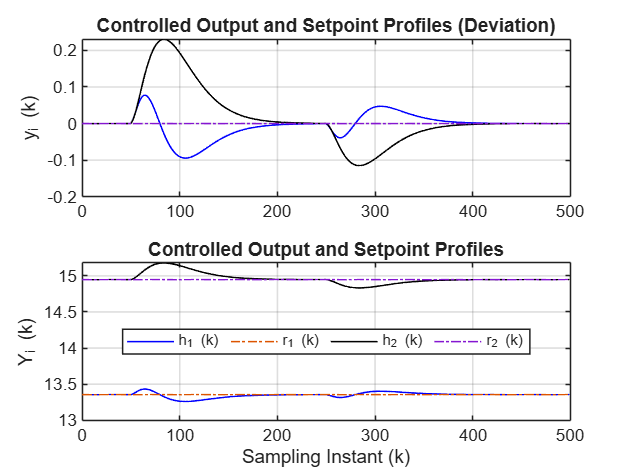

% <--------------MPC QP function---------------
% Inputs: Measurement and setpoint at instant k 
% Output: Manipulated input at instant k 

function [mpc, u_k ]  = MPCQP_StateSpace(mpc, y_k, r_k, k) 

  % Estimate model plant mismatch and filter it using unity gain filter 
    mpc.yhatk(:,k) = mpc.C_mat * mpc.xkhat(:,k) ; 
    mpc.dkhat(:,k) = y_k - mpc.yhatk(:,k) ;
  mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(mpc.n_op) - mpc.phy_d) * mpc.dkhat(:,k) ;
 
    % Target state computation using quadratic programming 
     
    options=optimoptions('quadprog', 'display', 'off');

    Fsk_vec = mpc.Fs_mat * ( r_k - mpc.Gain_e * mpc.dkhat_f(:,k))  ; 

    [us_k_QP, fsval] = quadprog(mpc.Hs_mat, Fsk_vec,mpc.As_mat, mpc.bs_vec, [],[],[],[],[], options )  ;
    mpc.us_k(:,k) = us_k_QP ; 
    mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * ( mpc.gam * mpc.us_k(:,k) + mpc.L_mat * mpc.dkhat_f(:,k))  ;
   
     Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)...
              - 2 * mpc.Su_mat' * mpc.WX_mat * (mpc.Ix_mat * mpc.xs_k(:,k) - mpc.Se_mat * mpc.dkhat_f(:,k))  ; 
  
    [Uf_k,FVAL] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, mpc.F_vec,[],[],[],[],[],options)  ;
    u_k = Uf_k(1:mpc.n_ip) ;  % Implement only optimal u(k) 

    % Internal MPC model: update from k to k+1
     mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * u_k + mpc.L_mat * mpc.dkhat(:,k) ;

end   %  End of MPC QP function 


**Display Simulation Results **

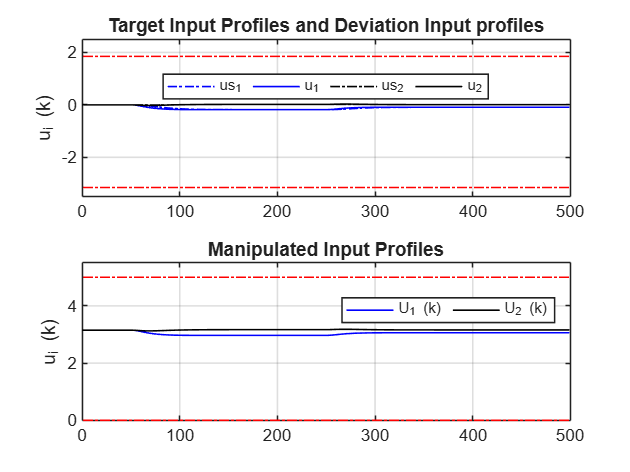

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;

u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;


**Controlled output profiles **

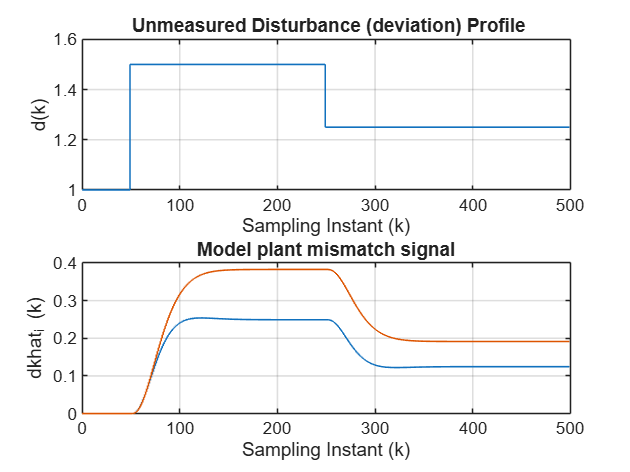

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')

legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

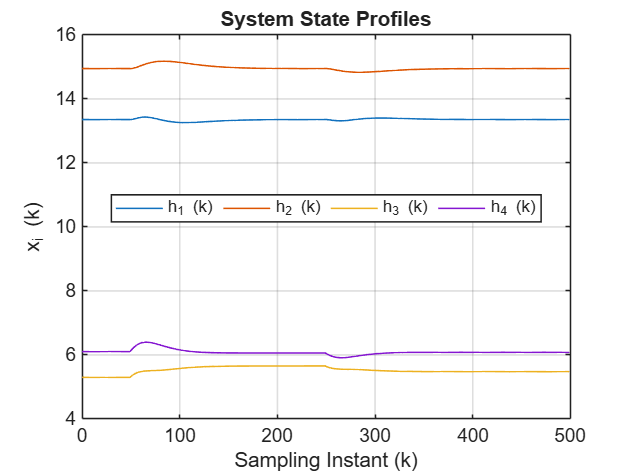

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)

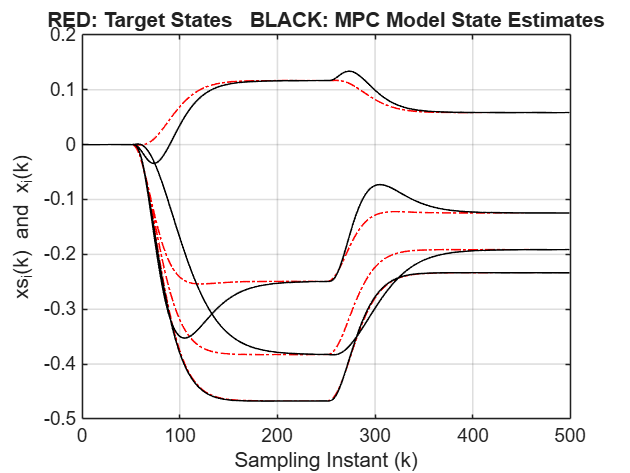

stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)

axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

**Disturbance input and Model Plant Mismatch profiles **

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

**System State profiles and MPC internal model profiles  **

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')
figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

Observe the results of simulation. The controlled outputs are tracking the desired values. 

**Task 10**: Let us change the operating point to Nonminimum phase and observe the results. Does the performance remain same? 

**Task 11: **Repeat the exercise for linear plant simulation. Now observe the plant model mismatch signal.

## Conclusions 

In this lesson, we have modified the vanilla MPC formulation that used the internal model as an open loop observer to an MPC formulation that uses a closed loop observer. Two formulations have been developed: State Space MPC and Output Tracking MPC. The State Space MPC has been converted to QP problem. Further, using Q-Tank simulations, different features of the State Space MPC have been demonstrated. Analysis of the simulation results reveals that 

- Use of closed loop observer significantly improves the disturbance rejection capability when compared with vanilla MPC based on open loop observer. The overshoot as well as the settling time reduce significantly with a closed loop observer is used for MPC formulation. 

- Disturbance filter help in reducing undue fluctuations in manipulated inputs by reducing effect of high frequency noise. 